# Matrixarray

The matrixarray class is meant to simplify operations over arrays of matrices. In the Loopless_computations script the operations are vectorized using the permute, reshape, repelem and repmat functions. To streamline this process the matrixarray is used. The example below shows how the matrixarray is build. In this example we take a local matrix for each element.

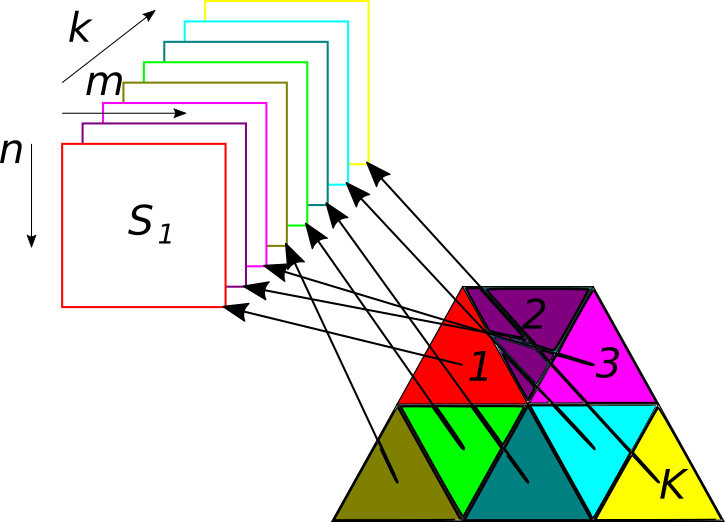

Here m and n are the size of the matrix and k corresponds to the triangles. Now if we for example want to multiply each local matrix by a material parameter differing on each element, we hit the current limits of what MATLAB's built-in routines can do.

Nd = 2;
Ne = 5;
A = [];
for i = 1:Ne
    A = cat(3, A, rand(Nd,Nd));
end
B = [];
for i = 1:Ne
    B = cat(3, B, rand(Nd,Nd));
end
Btemp = permute(B,[2,1,3]);

Here we created two sets of Ne, Nd by Nd matrices. Now we want to perform an element-wise matrix multiplication. For this we also need to create another matrix array Btemp which contains the transpose of the individual matrices in B.

I=[1 2 1 2];
J=[1 1 2 2];
Cn=dot(A(I,:,:),Btemp(J,:,:),2);
Cn = reshape(Cn,Nd,Nd,Ne);

Using matlabs built-in methods we either have to use a for loop or perform a vectorized operation using help variables like I and J. Finally we need to reshape the answer to receive the correct result matrices.

The matrixarray does exactly the same behind the scenes. First we generate our matrixarrays.

Am = ofem.matrixarray(A);
Bm = ofem.matrixarray(B);

Here we have to be careful that the data is entered correctly. Since we already had the correct structure before we only need to pass our data to the constructor.

Cm = Am*Bm;

The matrixarray class allows us to treat the element wise multiplication as a simple multiplication code-wise. 

sum(sum(sum(abs(Cm-Cn))))

ans = 0

Comparing the two results, we can see that they are exactly the same.

Currently the following operations are supported by the matrixarray:

- +

- -

- *

- .*

- /

- \

- reshape

- dot

- cross

- rot

- conj

- ctranspose

- transpose

Let us get back to the example of multiplying each individual element with a different material parameter. First we generate a set of Ne, Nd by Nd identity matrices.

A = [];
for i = 1:Ne
    A = cat(3,A,eye(Nd));
end
A = ofem.matrixarray(A);

Now for this easy example we generate a set of Ne material parameters in a matrixarray.

a(1,1,:) = 1:5;
a = ofem.matrixarray(a);

Now we can perform a multiplication of each individual element's matrix with the scalar material parameter.

A*a

ans =   2×2×5 matrixarray:

  double data:

(:,:,1) =

     1     0
     0     1


(:,:,2) =

     2     0
     0     2


(:,:,3) =

     3     0
     0     3


(:,:,4) =

     4     0
     0     4


(:,:,5) =

     5     0
     0     5


In the same way we can use the other basic operations.

A+a

ans =   2×2×5 matrixarray:

  double data:

(:,:,1) =

     2     1
     1     2


(:,:,2) =

     3     2
     2     3


(:,:,3) =

     4     3
     3     4


(:,:,4) =

     5     4
     4     5


(:,:,5) =

     6     5
     5     6


A-a

ans =   2×2×5 matrixarray:

  double data:

(:,:,1) =

     0    -1
    -1     0


(:,:,2) =

    -1    -2
    -2    -1


(:,:,3) =

    -2    -3
    -3    -2


(:,:,4) =

    -3    -4
    -4    -3


(:,:,5) =

    -4    -5
    -5    -4


A./a

ans =   2×2×5 matrixarray:

  double data:

(:,:,1) =

     1     0
     0     1


(:,:,2) =

    0.5000         0
         0    0.5000


(:,:,3) =

    0.3333         0
         0    0.3333


(:,:,4) =

    0.2500         0
         0    0.2500


(:,:,5) =

    0.2000         0
         0    0.2000


reshape(A,Nd,1,[])

ans =   2×1×10 matrixarray:

  double data:

(:,:,1) =

     1
     0


(:,:,2) =

     0
     1


(:,:,3) =

     1
     0


(:,:,4) =

     0
     1


(:,:,5) =

     1
     0


(:,:,6) =

     0
     1


(:,:,7) =

     1
     0


(:,:,8) =

     0
     1


(:,:,9) =

     1
     0


(:,:,10) =

     0
     1
